# COVID19 Social distancing detection system

## Algorithm design for the Social distancing

As part of an ongoing effort to keep our customers and others safe, and understanding that the only way through this is with global collaboration, we wanted to share the technical methodology we used to develop this software.

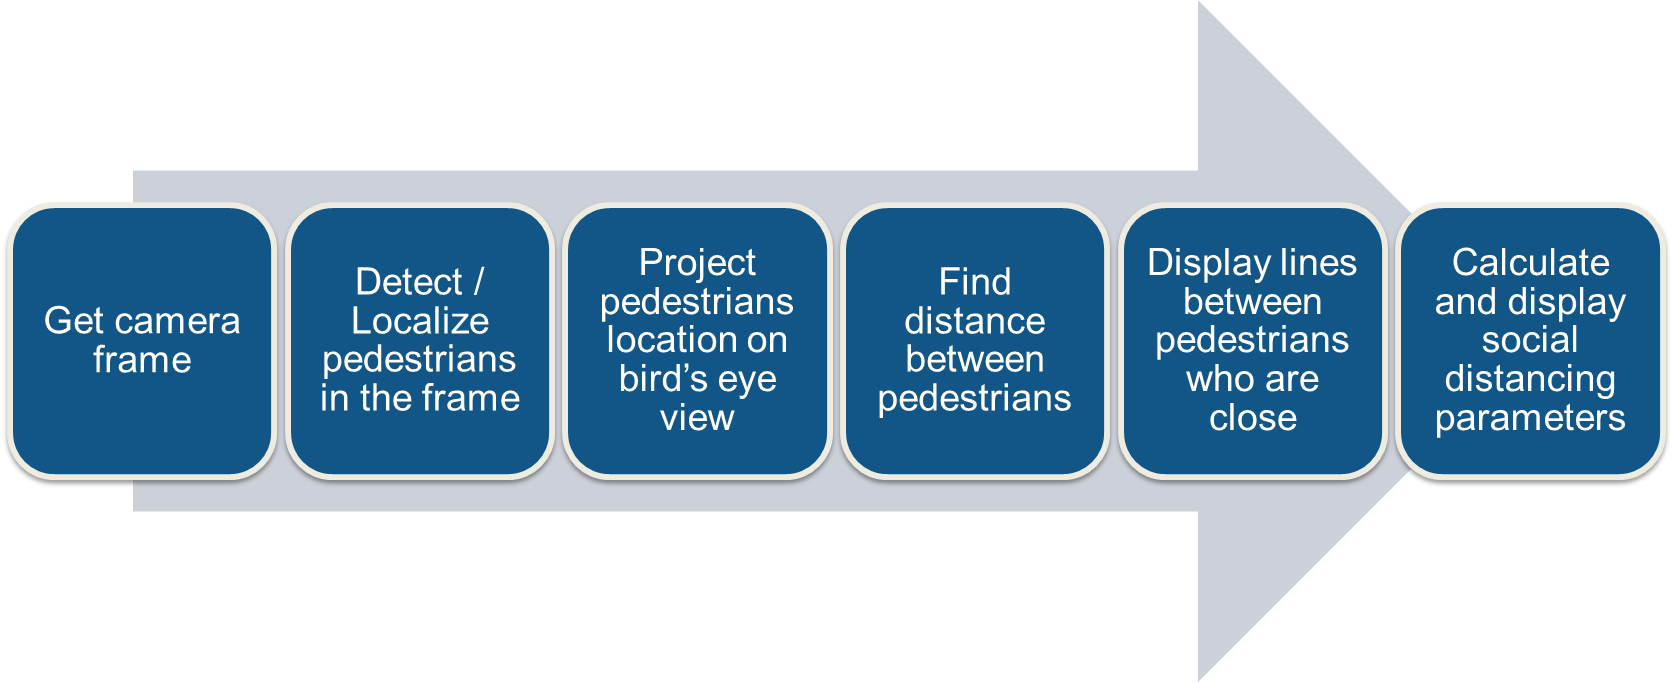

As a first step, we need to convert perspective view into bird's eye view for distance measurement. As the input frames are *monocular* (taken from a single camera), the simplest calibration method involves selecting four points in the perspective view and mapping them to the corners of a rectangle in the bird’s-eye view. This assumes that every person is standing on the same flat *ground plane*. 

clear all; clc;

- Run the code 'COVID19_PeopleExtractGT.mlx' first. You can download the dataset and get the sample image frame from the code.

I = imread('sample.jpg');
ori_size = size(I);
imshow(I)
h = drawpolyline('Color','green');
Porig = h.Position;

Convert selected 4 points into rectangle points, get the transformation matrix and warp the image.

Ppost = [1 1; 1080 1; 1080 1920; 1 1920];
T = fitgeotrans(Porig, Ppost,'projective'); 
[IBird, RB] = imwarp(I,T);
save T T RB

Visualize the points selected in the perspective view.

Psel = reshape(Porig', 1, []);
Ori = insertShape(I, 'FilledPolygon', Psel, 'LineWidth', 5, ...
    'Opacity', 0.5);
imshow(Ori)

Apply forward geometric transformation with the transformation matrix we got, and visualize those points(rectangle shape) in the bird eye view.

[x, y] = transformPointsForward(T, Porig(:,1), Porig(:, 2));
[xdataI,ydataI] = worldToIntrinsic(RB,x,y);
IBird2 = insertShape(IBird, 'FilledPolygon', reshape([xdataI, ydataI]', 1, []), "Opacity",0.5);
imshow(IBird2)

Load the pretrained yolov3 people detection model (Refer 'COVID19_TrainPeopleYOLOv3.mlx').

addpath("yolov3Helper\")
load('PeopleYOLOv3.mat');

Test the people detection model and get the bounding boxes information for distance measuring.

frame = I;
sz = size(frame);
resz =[227 227];
frame1 = im2single(imresize(frame, resz));

Convert to dlarray.

useGPU = false;
if useGPU
    XTest = gpuArray(dlarray(frame1,'SSCB'));
else
    XTest = dlarray(frame1, 'SSCB');
end

[bbox, score, label] = yolov3Detect(net, XTest, networkOutputs, anchorBoxes, anchorBoxMasks, ...
    0.5, 0.4, classNames);
bbox = bboxre(bbox, sz, resz)
detectedImg = frame;

if ~isempty(bbox)
    annotation = sprintf('%s', 'People');
    detectedImg = insertObjectAnnotation(detectedImg, 'rectangle', bbox, annotation, 'LineWidth', 3);
end
imshow(detectedImg)

Given the bounding box for each person, we estimate their (x, y) location in the bird’s-eye view. Since the calibration step outputs a transformation for the *ground plane*, we apply said transformation to the bottom-center point of each person’s bounding box, resulting in their position in the bird’s eye view

bottom_center = [bbox(:,1)+bbox(:,3)/2, bbox(:, 2) + bbox(:,4)];
t = insertMarker(detectedImg, bottom_center, 'o', 'size', 40, 'Color', 'r');
figure, imshow(t)

Apply forward geometric transformation with the transformation matrix we got, to the bird-eye's view.

[x, y] = transformPointsForward(T, bottom_center(:,1), bottom_center(:, 2));
[xdataI,ydataI] = worldToIntrinsic(RB,x,y);
T1 = insertMarker(IBird2, [xdataI, ydataI], "circle", "Size", 20, 'color', 'r');
imshow(T1)

Measure the distances between all the points(bottom center of bounding box) each other and set the threshould to meet 6-feet social distance.

d = pdist2([xdataI,ydataI], [xdataI,ydataI]);
d = triu(d)
[r, c] = find(d<0.5e3 & d>0)

Visualize the points we transformed, highlight people whose distance is below the minimum acceptable distance in red, and draw a line between to emphasize this.

idx = [r;c];               
plot(xdataI, ydataI, 'bo', 'MarkerFaceColor',"b", 'MarkerSize', 15); hold on
plot(xdataI(idx), ydataI(idx), 'ro', 'MarkerFaceColor',"r", 'MarkerSize', 15); hold off
for i = 1:length(r)
    line(xdataI([r(i);c(i)]), ydataI([r(i);c(i)]),'color','r')
end
axis equal
pbaspect([1 2 1])

Above method, while well-known, can be tricky to apply correctly. As such, we have built a lightweight tool that enables even non-technical users to calibrate the system in real time.

COVID19_SocialDistancing

### Helper Functions

function bbox = bboxre(bbox, sz, targetSize)
bbox(:,1) = bbox(:,1)*sz(2)/targetSize(2);
bbox(:,2) = bbox(:,2)*sz(1)/targetSize(1);
bbox(:,3) = bbox(:,3)*sz(2)/targetSize(2);
bbox(:,4) = bbox(:,4)*sz(1)/targetSize(1);
end

#### Predict Functions

function [bboxes,scores,labels] = yolov3Detect(net, XTest, networkOutputs, anchors, anchorBoxMask, confidenceThreshold, overlapThreshold, classes)
% The yolov3Detect function detects the bounding boxes, scores, and labels in an image.

imageSize = size(XTest,[1,2]);

% Find the input image layer and get the network input size.
networkInputIdx = arrayfun( @(x)isa(x,'nnet.cnn.layer.ImageInputLayer'), net.Layers);
networkInputSize = net.Layers(networkInputIdx).InputSize;

% Predict and filter the detections based on confidence threshold.
predictions = yolov3Predict(net,XTest,networkOutputs,anchorBoxMask);
predictions = cellfun(@ gather, predictions,'UniformOutput',false);
predictions = cellfun(@ extractdata, predictions, 'UniformOutput', false);
tiledAnchors = generateTiledAnchors(predictions(:,2:5),anchors,anchorBoxMask);
predictions(:,2:5) = applyAnchorBoxOffsets(tiledAnchors, predictions(:,2:5), networkInputSize);
[bboxes,scores,labels] = generateYOLOv3Detections(predictions, confidenceThreshold, imageSize, classes);

% Apply suppression to the detections to filter out multiple overlapping
% detections.
if ~isempty(scores)
    [bboxes, scores, labels] = selectStrongestBboxMulticlass(bboxes, scores, labels ,...
        'RatioType', 'Union', 'OverlapThreshold', overlapThreshold);
end
end

function YPredCell = yolov3Predict(net,XTrain,networkOutputs,anchorBoxMask)
% Predict the output of network and extract the confidence, x, y,
% width, height, and class.
YPredictions = cell(size(networkOutputs));
[YPredictions{:}] = predict(net, XTrain);
YPredCell = extractPredictions(YPredictions, anchorBoxMask);

% Apply activation to the predicted cell array.
YPredCell = applyActivations(YPredCell);
end

#### Utility Functions

function YPredCell = applyActivations(YPredCell)
YPredCell(:,1:3) = cellfun(@ sigmoid ,YPredCell(:,1:3),'UniformOutput',false);
YPredCell(:,4:5) = cellfun(@ exp,YPredCell(:,4:5),'UniformOutput',false);
YPredCell(:,6) = cellfun(@ sigmoid ,YPredCell(:,6),'UniformOutput',false);
end

function predictions = extractPredictions(YPredictions, anchorBoxMask)
predictions = cell(size(YPredictions, 1),6);
for ii = 1:size(YPredictions, 1)
    numAnchors = size(anchorBoxMask{ii},2);
    % Confidence scores.
    startIdx = 1;
    endIdx = numAnchors;
    predictions{ii,1} = YPredictions{ii}(:,:,startIdx:endIdx,:);
    
    % X positions.
    startIdx = startIdx + numAnchors;
    endIdx = endIdx+numAnchors;
    predictions{ii,2} = YPredictions{ii}(:,:,startIdx:endIdx,:);
    
    % Y positions.
    startIdx = startIdx + numAnchors;
    endIdx = endIdx+numAnchors;
    predictions{ii,3} = YPredictions{ii}(:,:,startIdx:endIdx,:);
    
    % Width.
    startIdx = startIdx + numAnchors;
    endIdx = endIdx+numAnchors;
    predictions{ii,4} = YPredictions{ii}(:,:,startIdx:endIdx,:);
    
    % Height.
    startIdx = startIdx + numAnchors;
    endIdx = endIdx+numAnchors;
    predictions{ii,5} = YPredictions{ii}(:,:,startIdx:endIdx,:);
    
    % Class probabilities.
    startIdx = startIdx + numAnchors;
    predictions{ii,6} = YPredictions{ii}(:,:,startIdx:end,:);
end
end

function tiledAnchors = generateTiledAnchors(YPredCell,anchorBoxes,anchorBoxMask)
% Generate tiled anchor offset.
tiledAnchors = cell(size(YPredCell));
for i=1:size(YPredCell,1)
    anchors = anchorBoxes(anchorBoxMask{i}, :);
    [h,w,~,n] = size(YPredCell{i,1});
    [tiledAnchors{i,2}, tiledAnchors{i,1}] = ndgrid(0:h-1,0:w-1,1:size(anchors,1),1:n);
    [~,~,tiledAnchors{i,3}] = ndgrid(0:h-1,0:w-1,anchors(:,2),1:n);
    [~,~,tiledAnchors{i,4}] = ndgrid(0:h-1,0:w-1,anchors(:,1),1:n);
end
end

function tiledAnchors = applyAnchorBoxOffsets(tiledAnchors,YPredCell,inputImageSize)
% Convert grid cell coordinates to box coordinates.
for i=1:size(YPredCell,1)
    [h,w,~,~] = size(YPredCell{i,1});  
    tiledAnchors{i,1} = (tiledAnchors{i,1}+YPredCell{i,1})./w;
    tiledAnchors{i,2} = (tiledAnchors{i,2}+YPredCell{i,2})./h;
    tiledAnchors{i,3} = (tiledAnchors{i,3}.*YPredCell{i,3})./inputImageSize(2);
    tiledAnchors{i,4} = (tiledAnchors{i,4}.*YPredCell{i,4})./inputImageSize(1);
end
end

*Copyright 2020 The MathWorks, Inc.*